# Allow access to files

addpath('Archive');
addpath('Control');
addpath('Data');
addpath('ID_functions');
addpath('Simulation_functions');
addpath('Simulink_files');

# Step 1: Reaction Wheel

parameters = struct;
h = 0.01;

% Data preparation
load('signal_3_12_5.mat');
y = angular_velocity.data(2:end);

[bphi, Jphi, k] = flywheel_ID(u', y, h);
parameters.bphi = bphi;
parameters.Jphi = Jphi;
parameters.k = k;

# Part 2 : Pendulum

clearvars -except parameters h

% Data preparation
load('signal_2_1_6.mat');
y = pendulum_angle.data(2:end);

[m, l, btheta, Jtheta] = pendulum_ID(u, y, h);
parameters.m = m;
parameters.l = l;
parameters.btheta = btheta;
parameters.Jtheta = Jtheta;

# Section 3 : Both

clearvars -except parameters h

% Data preparation
load('chirp2.mat');
y1 = pendulum_angle.data(2:end);
y2 = angular_velocity.data(2:end);
u = u(2:end);

% y = zeros(length(y1),1);
% for i = 1:length(y1)
%     y((i-1)*2+1) = y1(i);
%     y(i*2) = y2(i);
% end

[final_parameters, A, B, C, D] = full_system_ID(u,[y1 y2], h, parameters)

final_parameters = struct with fields:
         m: [1×1 param.Continuous]
         l: [1×1 param.Continuous]
    btheta: [1×1 param.Continuous]
    Jtheta: [1×1 param.Continuous]
      bphi: [1×1 param.Continuous]
      Jphi: [1×1 param.Continuous]
         k: [1×1 param.Continuous]


A =     0.9995    0.0100    0.0000
   -0.1015    0.9976    0.0004
         0         0    0.9922


B =    -0.0002
   -0.0438
    3.9462


C =      1     0     0
     0     0     1


D =      0
     0


# Chapter 4 : Nonlinear Validation

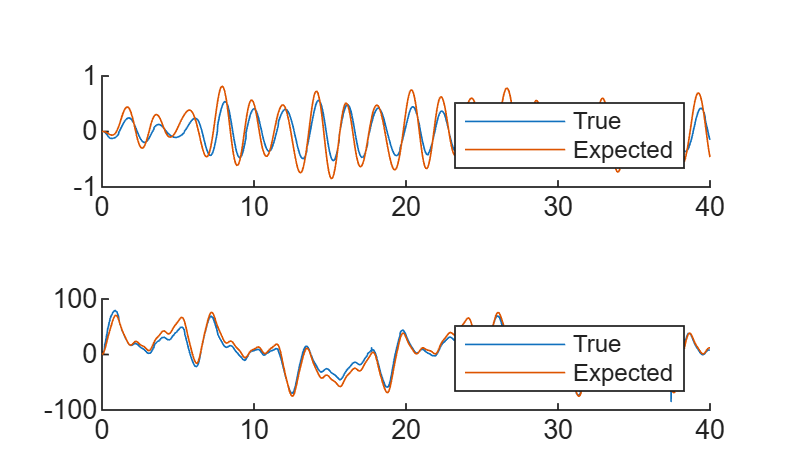

load('signal_1g_1_6.mat')
t = 0:h:(length(u)*h)-h;
y2 = angular_velocity.data;
y1 = pendulum_angle.data;
y1 = y1(2:end);
y2 = y2(2:end);
[yhat,xhat] = simsystem(A,B,C,[y1(1), 0.9*(y1(5)-y1(1))/(4*h), y2(1)], u);
y1hat = yhat(1:2:end); y2hat = yhat(2:2:end);

figure;
tiledlayout(1,2);
title("Verification Comparison")
nexttile
hold on
plot(0:h:(length(y1)*h-h),y1);
plot(t,y1hat);
legend("True", 'Expected');
nexttile
hold on
plot(0:h:(length(y2)*h-h),y2);
plot(t,y2hat);
legend("True", 'Expected');